# EFMouse: 1x1 montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 1x1 montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2024). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- stage 0 : Initialize. 

- stage 1: Define elecrodes and (optionally) a craniotomy.

- stage 2: Impose boundary conditions.

- stage 3: Export files for the FEM solver getDP.

- stage 4: Run the FEM solver.

- stage 5: Map the results to the Allen mouse atlas.

### Stage 0: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.dir = '/Users/rubensanchez/desktop/EFMouse/1x1Montage'; % Results and the object (4x1.mat) will be saved here.
o.ID = '1x1';  % A name/tag for this simulation.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

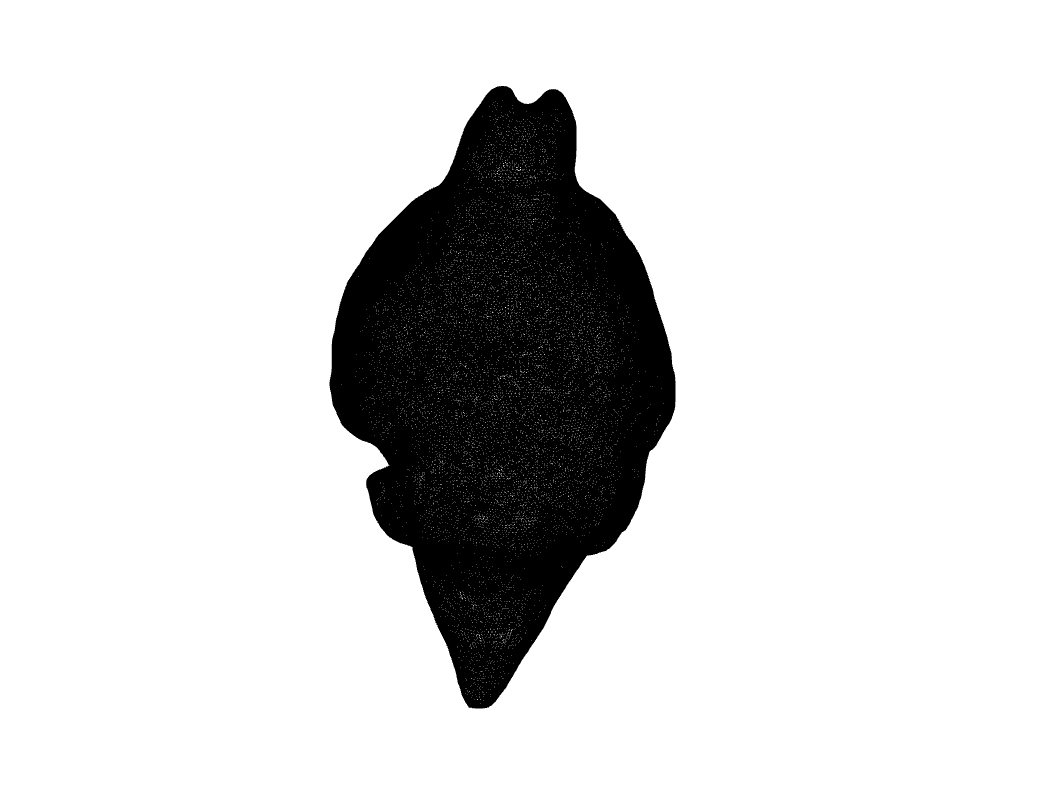

plotMesh(o)

The mesh is pretty dense, so it will look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage 1: Create electrodes and a craniotomy

Now we define a 1x1 stimulation montage: 1 electrode on the anterior and 1 return electrode on the posterior targeting visual areas.  

o.eTag = ["Anterior" "Posterior"];
% currents need to sum to 0. (In milliamps (mA) units.)
o.eCurrent = [0.2,-0.2];
% center coordinate of the electrode position (in mesh space) 
o.eCenter = [-3.56,29.5,5.45;
             -3.43,24.8,6.02]';
% radius of the electrodes (in mesh space units) (1 mesh unit ~ 1 mm)
o.eRadius = [0.71,0.67]

o = EF Mouse Model (label: 1x1) in directory /Users/rubensanchez/desktop/EFmouse/1x1Montage (stage=0).

Add a craniotomy:

% center coordinate of the craniotomy position (in mesh space)
o.cCenter = [-3.4236,27.1067,5]';
% radius of the creaniotomy (in mesh space units) (1 mesh unit ~ 1 mm)
o.cRadius = 1.5;

To add these to the model, we run the pipeline to stage 1. With `show=true`, this also opens a figure for inspection of the mesh:

Compute stage 1 - computeMesh
EF Mouse Model (label: 1x1) in directory /Users/rubensanchez/desktop/EFmouse/1x1Montage (stage=0).
-Creating craniotomy-
 Craniotomy: touching tissue:
   gray: num elements = 6884
   csf: num elements = 6083
   bone: num elements = 8247
   skin: num elements = 1551
 Craniotomy only removes skin and bone.
-Creating 2 electrodes-
 Electrode: Anterior: touching tissue:
   skin: num elements = 39
   Creating electrode Anterior in max touched tissue: skin.
 Electrode: Posterior: touching tissue:
   skin: num elements = 46
   Creating electrode Posterior in max touched tissue: skin.


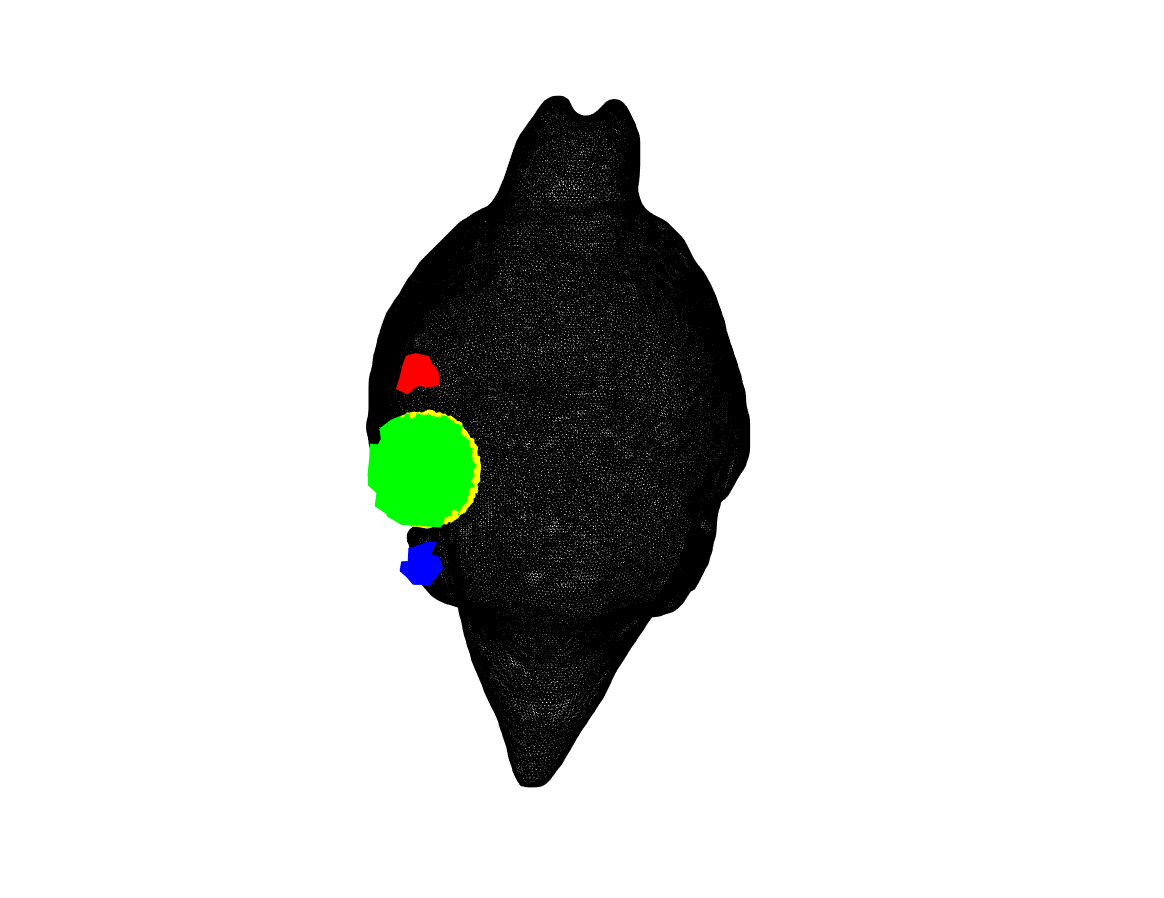

Stage 1 complete - 55.2511 seconds 


o.run(targetStage=1,show=true)

This mesh now shows the electrodes in red and blue (return), for the craniotomy, skin removal is shown in green and skull removal shown in yellow.

### Stage 2: Find the electrode boundaries and add to the mesh

In this stage, EFMouse searches for the edges of the electrodes as this is where the current flows into the model. The boundary conditions of the Laplace equation are set here. 

o.run(targetStage=2)

Compute stage 2 - computeBoundary
                 Electrode Area
                 ______________

    Anterior        0.78309    
    Posterior       0.67532    

Stage 2 complete - 64.3021 seconds 


### Stage 3: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in *1x1.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=3)

Compute stage 3 - export data
----Starting saveMesh...01-Jul-2024 18:18:00
----saveMesh elapsed time: 30.8995 seconds

----Starting savePro...01-Jul-2024 18:18:31
----savePro elapsed time: 0.0983 seconds

Stage 3 complete - 52.4994 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFmouse on 01-Jul-2024 18:18:31 
 ID: 1x1 
 Dir: /Users/rubensanchez/desktop/EFmouse/1x1Montage 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
craniotomy = Region[6];
skinremoved = Region[7];
Anterior = Region[8];
Posterior = Region[9];
boundaryAnterior = Region[10];
boundaryPosterior = Region[11];
DomainC = Region[{gray,csf,bone,skin,eye,craniotomy,skinremoved,Anterior,Posterior}];
AllDomain = Region[{gray,csf,bone,skin,eye,craniotomy,skinremoved,Anterior,Posterior,boundaryAnterior,boundaryPosterior}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[craniotomy] = 1.654;
sigma[skinremoved] = 2.5e-14;
sigma[Anterior] = 5.9e+07;
sigma[Posterior] = 5.9e+07;
du_dn1[] = 255.398816;
du_dn2[] = -296.157649;
}

Jacobian {
  { Name Vol ;
    Case {
      { Region All ; Jacobian Vol ; }
    }
  }
  { Name Sur ;
    Case {
      { Region All ; 

This file can be opened in the getDP gui to run it manually, but stage 4 runs it for you.

### Stage 4: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=4,show=false);

Compute stage 4 - computeField
Info    : Running '/Users/rubensanchez/Desktop/roast/EFmouse_class/efMouseMod/lib/getdp-3.2.0/bin/getdpMac /Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1.msh -pos Map' [GetDP 3.2.0, 1 node, max. 1 thread]
Info    : Started (Mon Jul  1 18:20:02 2024, Wall = 0.0769172s, CPU = 0.053779s, Mem = 5.38672Mb)
Info    : Initializing Gmsh
Error   : Unknown number option 'General.NativeFileChooser'
Info    : Loading problem definition '/Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1.msh'
Info    : System 'Sys_Ele' : Real
P r e - P r o c e s s i n g . . .
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : Pre-processing                                          
 20

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...01-Jul-2024 18:58:17


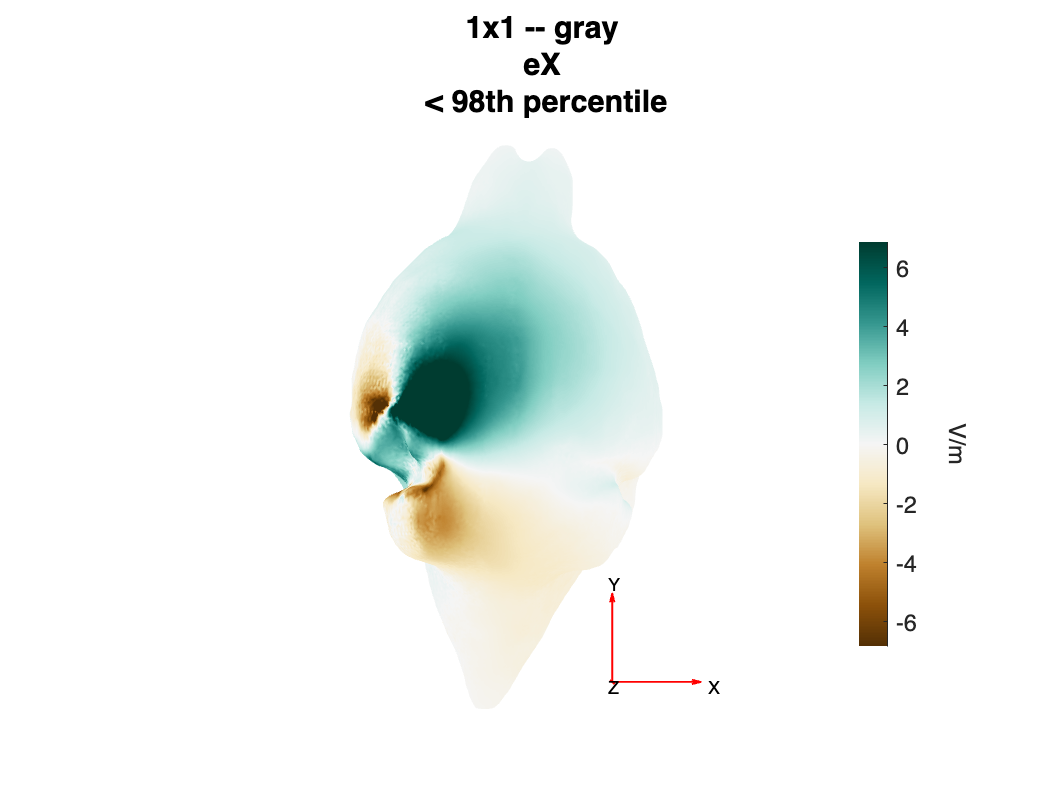

----plotEf elapsed time: 5.9921 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...01-Jul-2024 18:58:23


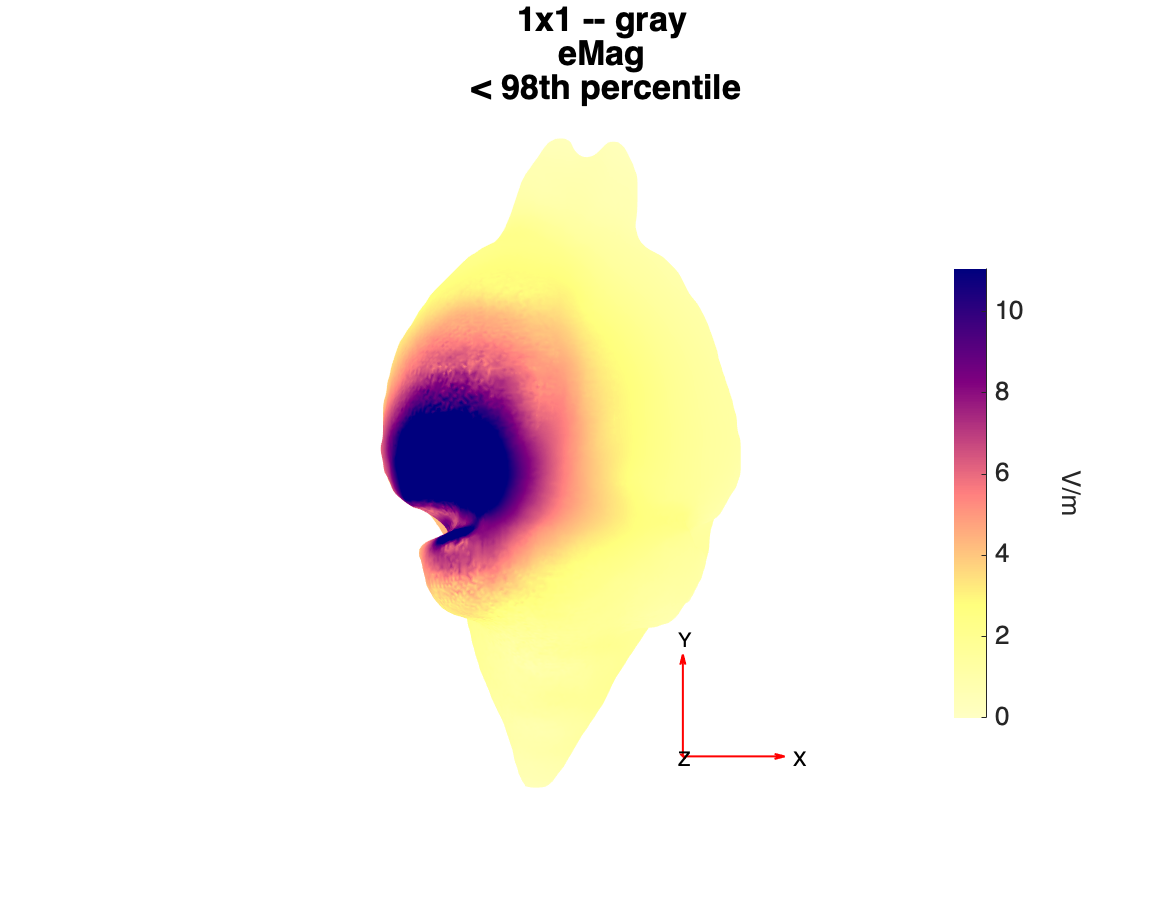

----plotEf elapsed time: 2.0585 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o)

----Starting analyzeTissue...01-Jul-2024 18:59:13
Electric field summary statistics for gray tissue
             mean       median      std        min       max  
            _______    ________    ______    _______    ______

    eX      0.79299     0.67688    1.6794    -11.718    26.464
    eY      -1.6743     -1.3555    2.2744    -31.965    19.517
    eZ      -0.7507    -0.39775    2.1183    -40.614    12.768
    eMag     2.8329      1.9901     2.907    0.16347    46.878

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.7158, for ef_norm_mean: (0.311 -0.591 -0.258)

Electric field summary statistics for csf tissue
             mean       median      std        min       max<

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality the reference area is the rest of the gray tissue. 

roi.shape = 'box';
roi.dim = [[-4.0087 -2.56];[26.4022 27.64];[3 4]]';% Define the limits of the box ROI (x,y,z)(in mesh space units) (1 mesh unit ~ 1 mm)
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.

----Starting analyzeRoi...01-Jul-2024 19:00:41
Electric field summary statistics for a box roi in gray
              mean       median      std        min        max  
            _________    _______    ______    _______    _______

    eX         2.5123     2.5692    1.1623    -1.4944     5.4232
    eY        -8.5358    -7.9802     3.063    -16.525    -2.7663
    eZ      -0.062983    0.44015    2.6286    -9.1839      4.856
    eMag       9.4239     8.6681    2.8276     5.3249     18.619

Relative focality = 1.1959% of 161805 reference nodes (eMag > 75.00% of the ROI max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9392, for ef_norm_mean: (0.296 -0.891 0.023)


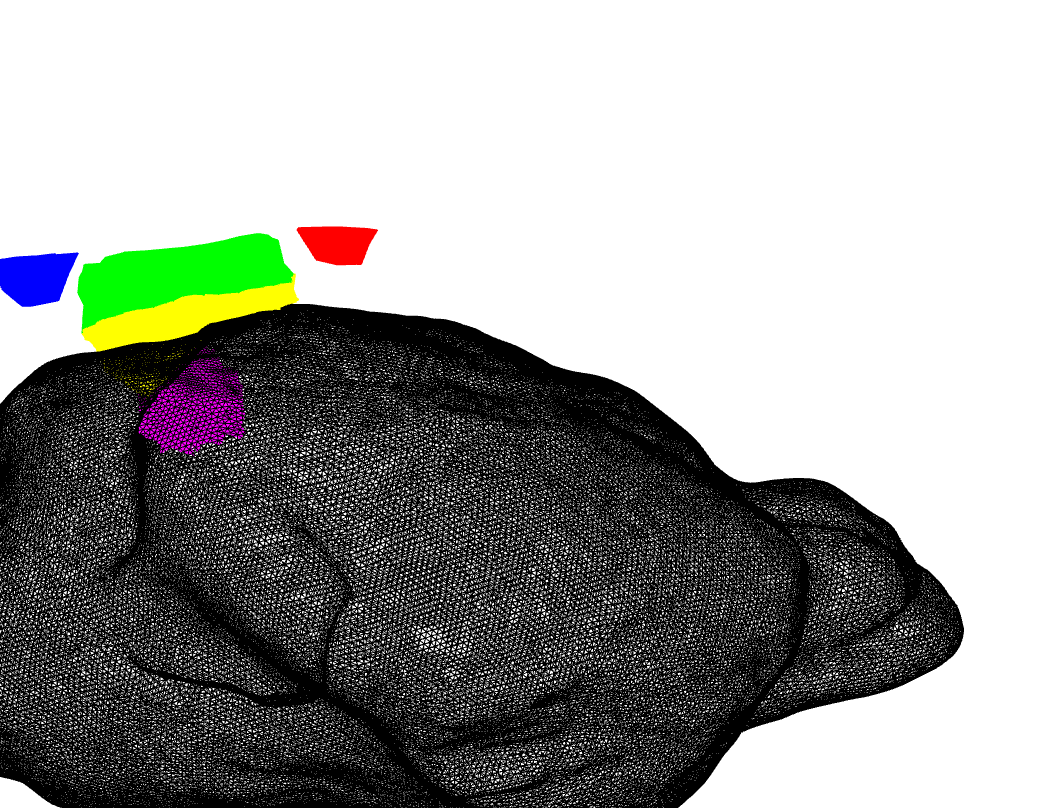

% Rotate and zoom to view the (purple) box ROI underneath the craniotomy
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an homologous box ROI but in the right hemisphere

roi_control.shape = 'box';
roi_control.dim = [[2.56 4.0087];[26.4022 27.64];[3 4]]';% Define the limits of the box ROI (in mesh space units)
summary = analyzeRoi(o,roi_control,plot=true,foc_percentile_max=99.9,foc_threshold=75);

----Starting analyzeRoi...01-Jul-2024 19:00:49
Electric field summary statistics for a box roi in gray
              mean       median       std        min         max  
            ________    ________    _______    ________    _______

    eX       0.20141     0.27985    0.29016    -0.64429     0.7175
    eY       -1.6552     -1.6222    0.27954     -2.4277    -1.0444
    eZ      -0.15023    -0.15194    0.11007     -0.4589    0.17793
    eMag      1.7029      1.6824    0.27753      1.1081     2.4321

Relative focality = 57.2193% of 161865 reference nodes (eMag > 75.00% of the ROI max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9823, for ef_norm_mean: (0.111 -0.971 -0.095)


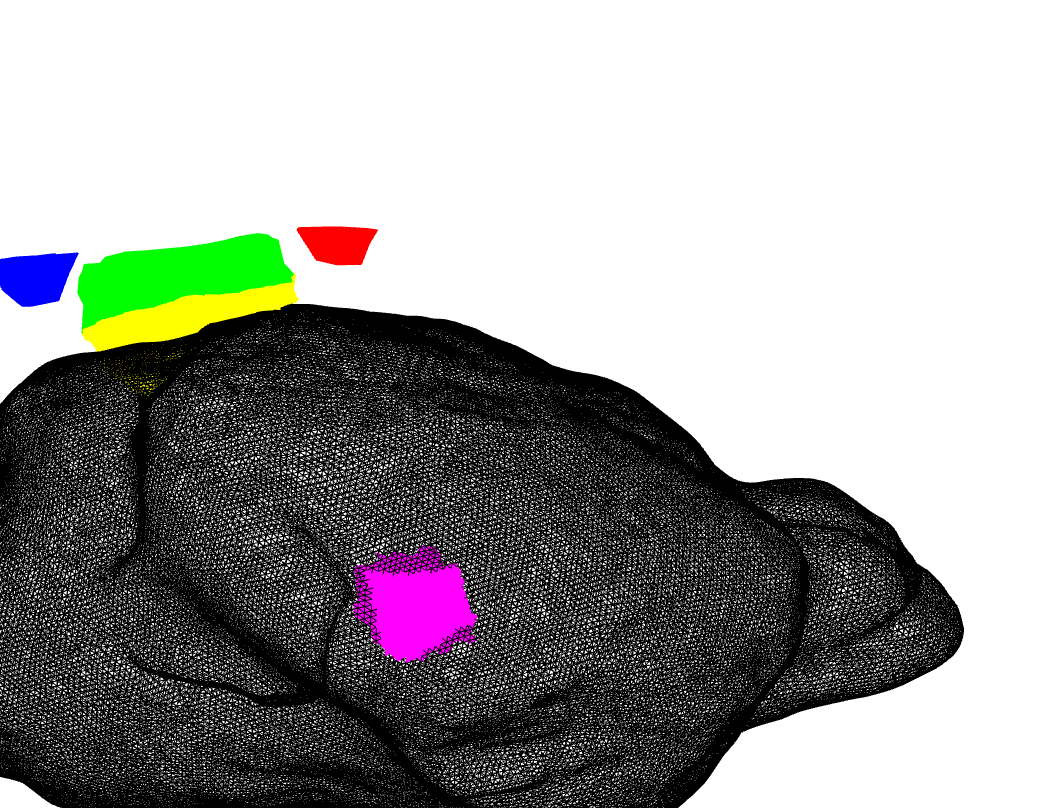

% Rotate and zoom to view the (purple) box ROI underneath the craniotomy
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage 5: Volumetric Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage 5 of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=5,startStage=5)

Compute stage 5 - computeVoxelSpace
----Starting computeVoxelSpace...01-Jul-2024 19:01:21
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1_efm.nii.gz created
---/Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1_efX.nii.gz created
---/Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1_efY.nii.gz created
---/Users/rubensanchez/desktop/EFmouse/1x1Montage/1x1_efZ.nii.gz created
----computeVoxelSpace elapsed time: 27.8831 seconds


### Atlas Based Analysis

Once stage 5 has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...01-Jul-2024 19:02:46
Area: Visual areas (1.0% of brain) , hemisphere left 
             mean      median      std         min        max  
            _______    _______    ______    _________    ______

    eX       4.7816     3.8599    4.6812      -5.4848    23.523
    eY      -10.723    -10.354    5.2165      -28.129    3.3482
    eZ      -3.4174    -2.1581    5.6399      -31.189     10.11
    eMag     13.909     12.969    6.1341    0.0061045    36.793

Relative focality = 0.1190% of 92410 reference voxels (eMag > 75.00% of the area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.8764, for ef_norm_mean: (0.342 -0.787 -0.176)
----analyzeAtlas elapsed time: 1.5234 seconds


For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...01-Jul-2024 19:02:47
Area: Visual areas (1.0% of brain) , hemisphere right 
               mean        median        std         min         max  
            __________    _________    _______    _________    _______

    eX         0.51646      0.37269    0.48088     -0.60438     2.2759
    eY         -1.9512      -2.1449    0.83912      -3.5042          0
    eZ      -0.0027768    -0.063365    0.27453     -0.76167    0.81006
    eMag        2.0683       2.2373    0.89994    0.0022396     3.5414

Relative focality = 48.2127% of 92457 reference voxels (eMag > 75.00% of the area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9763, for ef_norm_mean: (0.241 -0.946 -0.002)
----analyzeAtlas elapsed ti

## Tips and Tricks

- The run function can be called with any `targetStage` from 0 to 5. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial and also know the stage:

o = EFMouse(dir='/Users/rubensanchez/desktop/EFMouse/1x1Montage',ID='1x1')

o = EF Mouse Model (label: 1x1) in directory /Users/rubensanchez/desktop/EFmouse/1x1Montage (stage=5).